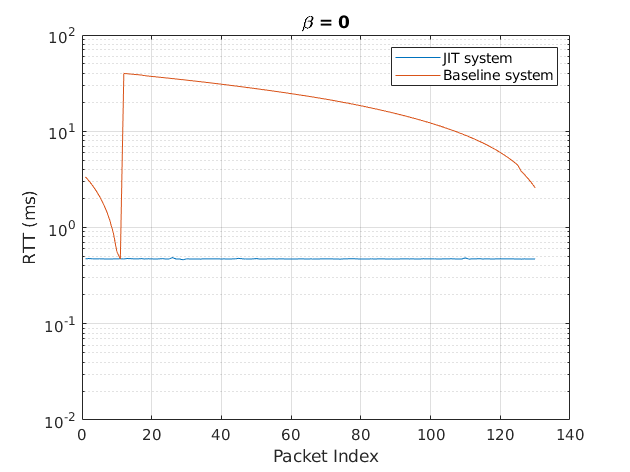

RTT_JIT  = [0.000472065,0.000476043,0.000471846,0.000471990,0.000472920,0.000471477,0.000471249,0.000470190,0.000471423,0.000472323,0.000473379,0.000471084,0.000476550,0.000474171,0.000472092,0.000471594,0.000474381,0.000470955,0.000473211,0.000471780,0.000470802,0.000471528,0.000474324,0.000471396,0.000470979,0.000487347,0.000470175,0.000470883,0.000462294,0.000472452,0.000470874,0.000471153,0.000470442,0.000469866,0.000472395,0.000471903,0.000471684,0.000471423,0.000472116,0.000471120,0.000471522,0.000470526,0.000471081,0.000472338,0.000478107,0.000472749,0.000470661,0.000471147,0.000471363,0.000475512,0.000470484,0.000471288,0.000471228,0.000472746,0.000471858,0.000470544,0.000472662,0.000471318,0.000471321,0.000471288,0.000470079,0.000471384,0.000472584,0.000471150,0.000471243,0.000471609,0.000470001,0.000470862,0.000472257,0.000472551,0.000472377,0.000471459,0.000470463,0.000469569,0.000471282,0.000472407,0.000473490,0.000473049,0.000471699,0.000470793,0.000471060,0.000470514,0.000471798,0.000470989,0.000471573,0.000472365,0.000471246,0.000471081,0.000471438,0.000470910,0.000470943,0.000472860,0.000471954,0.000471336,0.000471657,0.000471033,0.000470718,0.000472947,0.000472116,0.000471507,0.000472698,0.000470871,0.000470820,0.000472203,0.000472626,0.000472917,0.000471441,0.000471219,0.000470976,0.000482721,0.000469887,0.000471738,0.000472215,0.000473880,0.000471339,0.000471426,0.000471537,0.000470871,0.000471852,0.000472947,0.000472224,0.000471801,0.000472470,0.000471297,0.000471150,0.000469767,0.000471579,0.000470901,0.000470556,0.000470658];
RTT_JIT = RTT_JIT*1000;

RTT_BL = [0.003355320,0.003052056,0.002739612,0.002427516,0.002114775,0.001800774,0.001493775,0.001180479,0.000872391,0.000562029,0.000471249,0.039909019,0.039599460,0.039289105,0.038980078,0.038670420,0.038362483,0.037744842,0.037434544,0.037122643,0.036809272,0.036495304,0.036181671,0.035867005,0.035552797,0.035238312,0.034922449,0.034606375,0.034290777,0.033975259,0.033659635,0.033343500,0.033026722,0.032710104,0.032394241,0.032077507,0.031761678,0.031447891,0.031128781,0.030811260,0.030494068,0.030178315,0.029863170,0.029547118,0.029233623,0.028919538,0.028607608,0.028293657,0.027982864,0.027672766,0.027364431,0.027054331,0.026745937,0.026436927,0.026129434,0.025819989,0.025512456,0.025208497,0.024899232,0.024593638,0.024287893,0.023979555,0.023673736,0.023372239,0.023069196,0.022763113,0.022455897,0.022147362,0.021837988,0.021528906,0.021215607,0.020902669,0.020588664,0.020275855,0.019962817,0.019648575,0.019334170,0.019021443,0.018709071,0.018395020,0.018080961,0.017767503,0.017453119,0.017140587,0.016826796,0.016512880,0.016199649,0.015886618,0.015573978,0.015263184,0.014950558,0.014640075,0.014328882,0.014018962,0.013708956,0.013398738,0.013090644,0.012781251,0.012472194,0.012162669,0.011855550,0.011547784,0.011249835,0.010927371,0.010619053,0.010312392,0.010008021,0.009698811,0.009390138,0.009085971,0.008778267,0.008474358,0.008170482,0.007866573,0.007559805,0.007254565,0.006947865,0.006638718,0.006327906,0.006016062,0.005703108,0.005390622,0.005078763,0.004766649,0.004455558,0.003834334,0.003522933,0.003211821,0.002900064,0.002588385,0.002276475,0.001965135,0.001653222,0.001349103,0.001030125,0.000717222,0.039753763,0.039443623,0.039133338,0.038823223,0.038514586,0.038207553,0.037898392];
RTT_BL = RTT_BL*1000;

packet = (1:length(RTT_JIT));

semilogy(packet, RTT_JIT); 
hold on;
semilogy(packet, RTT_BL(1:length(RTT_JIT)));

grid on;
xlabel("Packet Index")
ylabel("RTT (ms)")
ylim([10e-3 100])
legend("JIT system","Baseline system")
title('\beta = 0')



Process_delay_client = RTT_BL(1:length(RTT_JIT))-RTT_JIT;



